x = sym('x','real');
global_bFun = basisFunction("Lagrange",2,x,[4 5]);
global_bFun.basis

$$ans(x) = \left(\begin{array}{c} \left(2\,x-9\right)\,\left(x-5\right)\\ -\left(2\,x-8\right)\,\left(2\,x-10\right)\\ \left(2\,x-9\right)\,\left(x-4\right) \end{array}\right)$$


xi = sym('xi','real');
local_bFun = basisFunction("Lagrange",2,xi,[-1 1]);
local_bFun.basis

$$ans(xi) = \left(\begin{array}{c} \xi \,\left(\frac{\xi }{2}-\frac{1}{2}\right)\\ -\left(\xi -1\right)\,\left(\xi +1\right)\\ \xi \,\left(\frac{\xi }{2}+\frac{1}{2}\right) \end{array}\right)$$

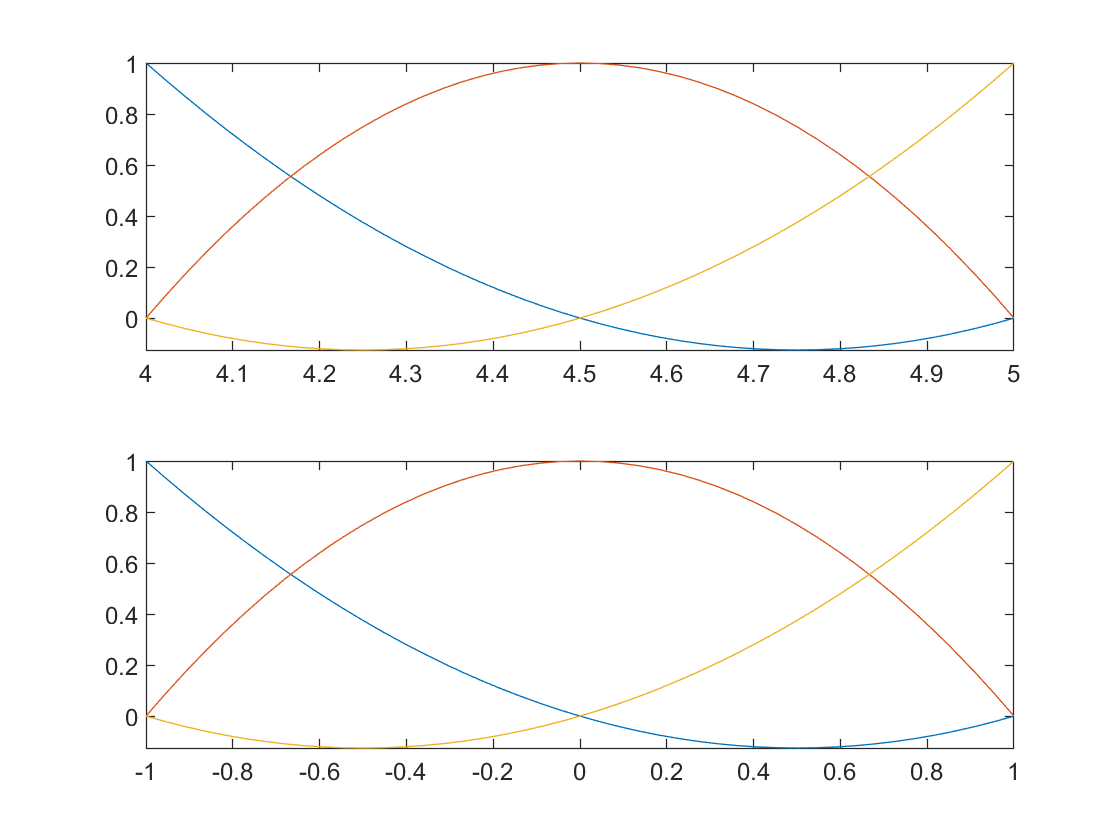


figure
subplot(2,1,1)
fplot(global_bFun.basis,[4 5])
subplot(2,1,2)
fplot(local_bFun.basis,[-1 1])


xi_x = computeAffineMapping([-1 1], [4 5], x)

$$xi\_x(x) = 2\,x-9$$

x_xi = computeAffineMapping([4 5], [-1 1], xi)

$$x\_xi(xi) = \frac{\xi }{2}+\frac{9}{2}$$


local_bFun.basis(xi_x)

$$ans = \left(\begin{array}{c} \left(2\,x-9\right)\,\left(x-5\right)\\ -\left(2\,x-8\right)\,\left(2\,x-10\right)\\ \left(2\,x-9\right)\,\left(x-4\right) \end{array}\right)$$

global_bFun.basis(x_xi)

$$ans = \left(\begin{array}{c} \xi \,\left(\frac{\xi }{2}-\frac{1}{2}\right)\\ -\left(\xi -1\right)\,\left(\xi +1\right)\\ \xi \,\left(\frac{\xi }{2}+\frac{1}{2}\right) \end{array}\right)$$


figure
subplot(2,1,1)
fplot(local_bFun.basis(xi_x),[4 5])
subplot(2,1,2)
fplot(global_bFun.basis(x_xi),[-1 1])

function F = computeAffineMapping(TargetSpace, Preimage, Domain)
A = [1 Preimage(1); 1 Preimage(2)];
b = [TargetSpace(1); TargetSpace(2)];
c = A\b;

F(Domain) = c(1) + c(2)*Domain;
end